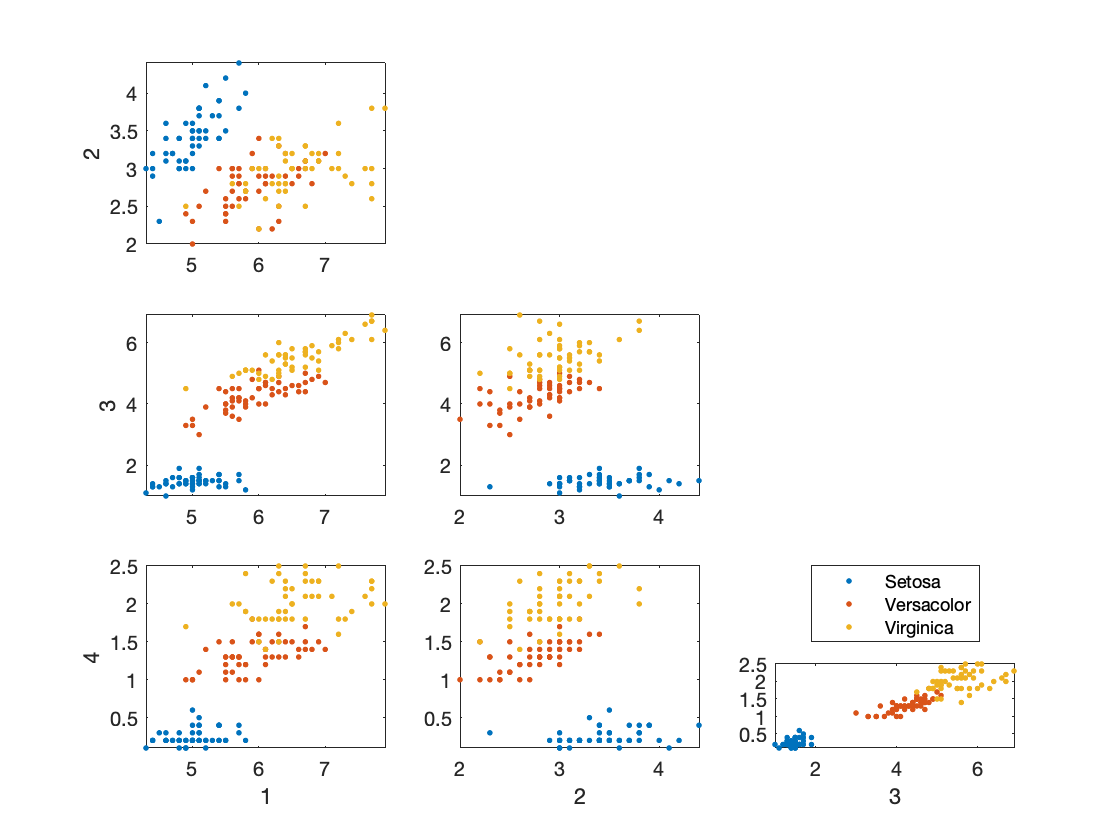

% PCA

% Clustering by K-means
%cd data
iris_setosa = load('iris_setosa.txt','-ascii');
iris_versicolor = load('iris_versicolor.txt','-ascii');
iris_virginica = load('iris_virginica.txt','-ascii');
%cd ..

irisdata = [iris_setosa;iris_versicolor;iris_virginica];

figure(100);
% label groups, just like for ANOVA
G = [repmat(1,size(iris_setosa,1),1);
     repmat(2,size(iris_versicolor,1),1);
     repmat(3,size(iris_virginica,1),1);];
scatterplot(irisdata,'class',G,'markersize',8);
legend('Setosa','Versacolor','Virginica','Location','NorthOutside')

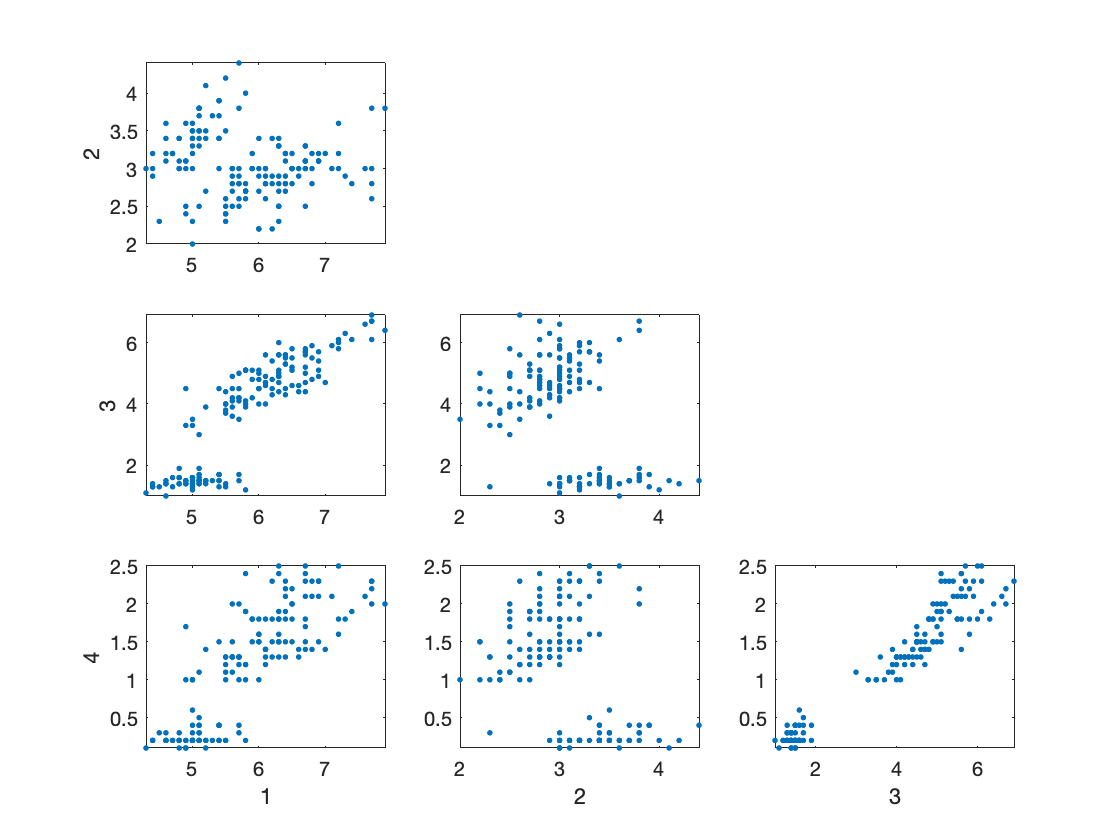

cd .. 

figure(101);
scatterplot(irisdata,'markersize',8);

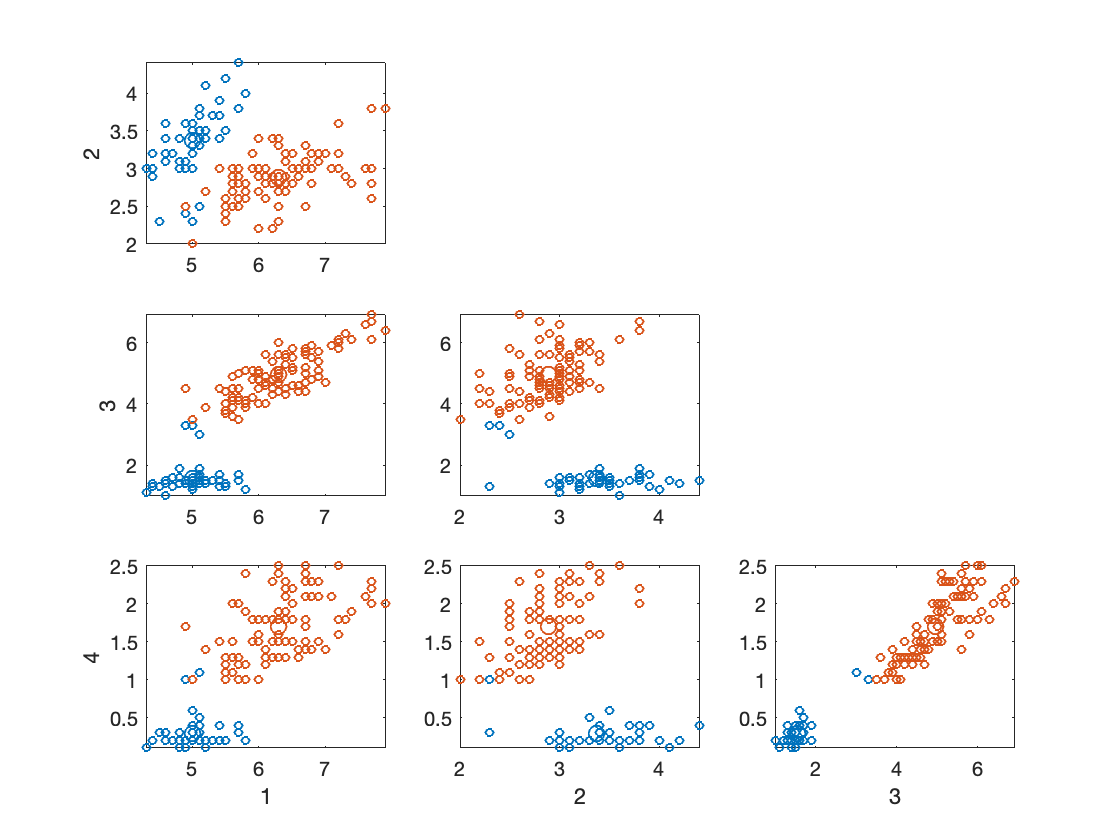


K = 2;
[idx,c] = kmeans(irisdata,K);
figure(102);
clf; % clear the figure;
scatterplot(irisdata,'class',idx,'markersize',4,'marker','o');
scatterplot(c,'class',[1:size(c,1)]','marker','o','markersize',8,'shrink',0);

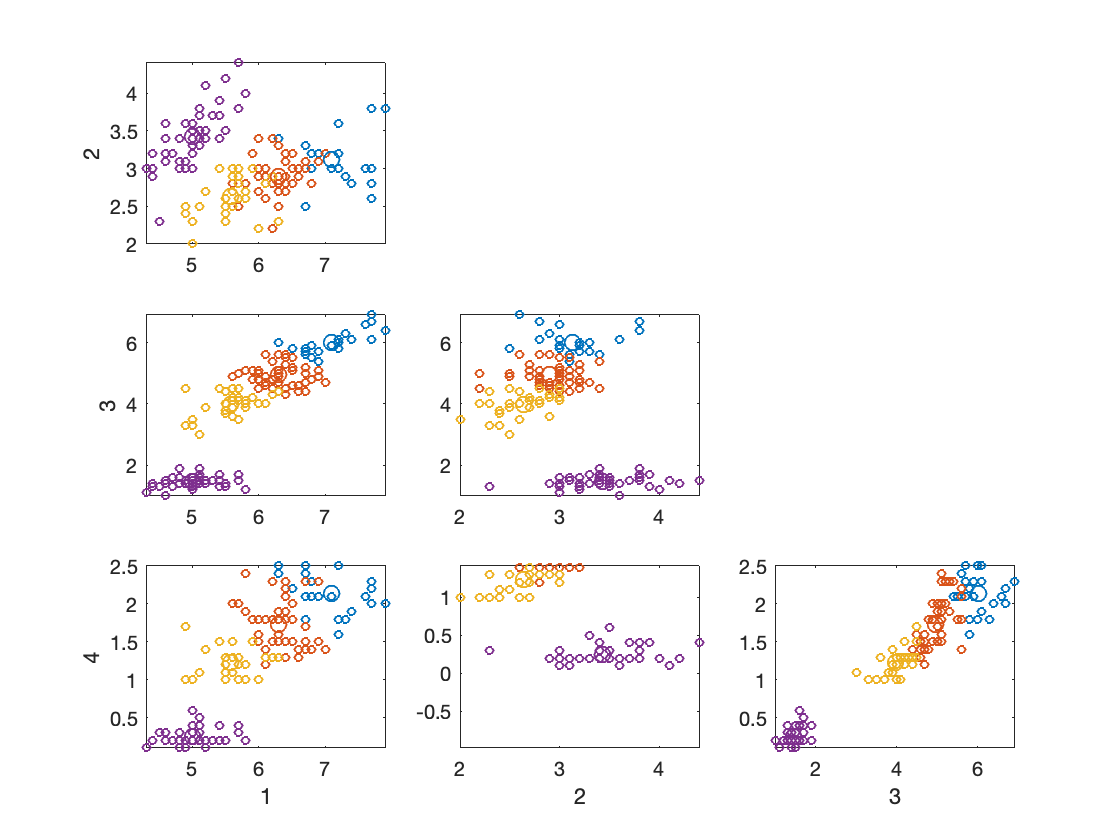



% Progress of kmeans over time - change k parameter
%kmeans_over_time(irisdata,4);

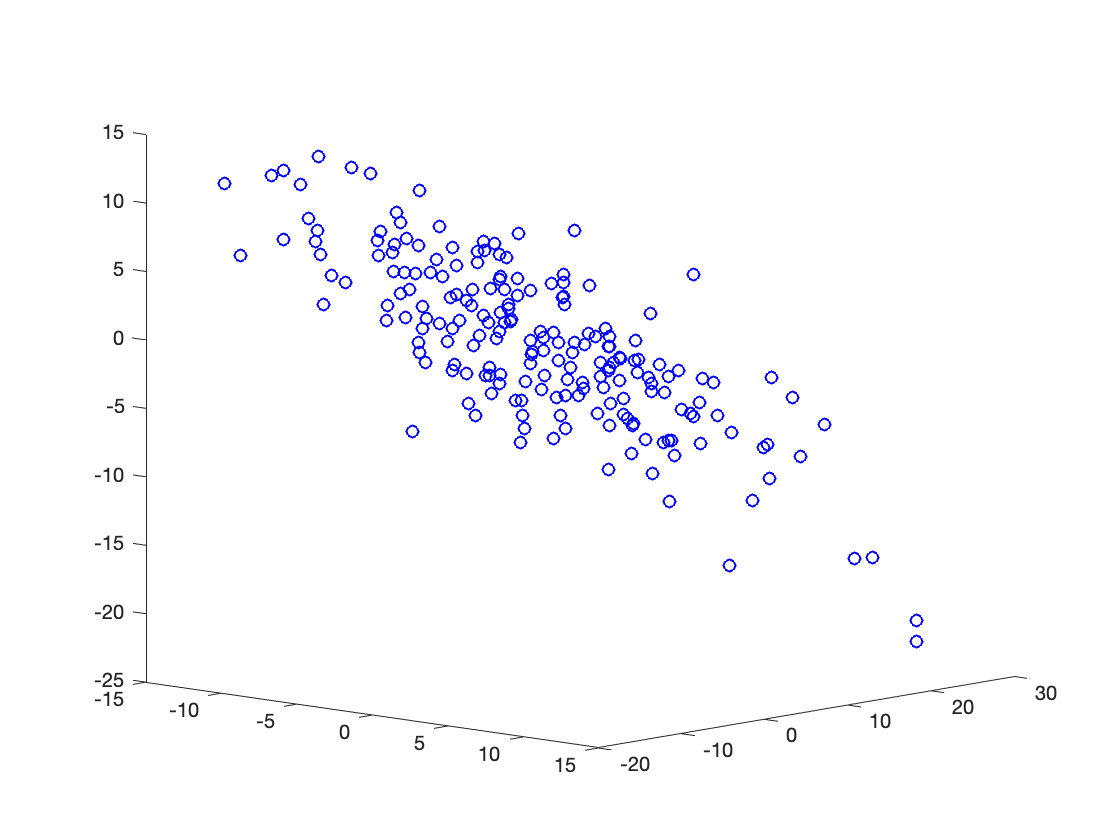



%------------------------

% PCA - identifying informative dimensions


g = rot3d(30*pi/180,1)*rot3d(45*pi/180,2)*...
        [10 0 0 ; 0 4 0 ; 0 0 0.3]  * randn(200,3)';
figure;
plot3(g(1,:),g(2,:),g(3,:),'bo')
view(48,38);

% Use rotate tool in the figure tool bar, rotate the view; 
% is there a few where the data looks really "thin", meaning there isn't 
% much that much variation in that dimension



% ------
% Implement PCA using covariance matrix

% Note that g has 3 dimensions, and 200 data points/pbservations

V = cov(g');  % calculate covariance matrix
             % I transposed the data in g so each row would have 1 data point
             % the answer V should have dimension 3x3
             
[comps,factor, explained] = pcacov(V);  
% comps = coefficients of PCs in columns. 3 PCs generated.
% factor = latent, variances of each principle compoenent
% or eigenvalues of covariance matrix
% explained = percentage of variance explained


%---------
totalvariance = sum(factor)

totalvariance = 116.3412

varexplained = 100 * factor ./ sum(totalvariance) % same as "explained"

varexplained =    86.3895
   13.5326
    0.0779


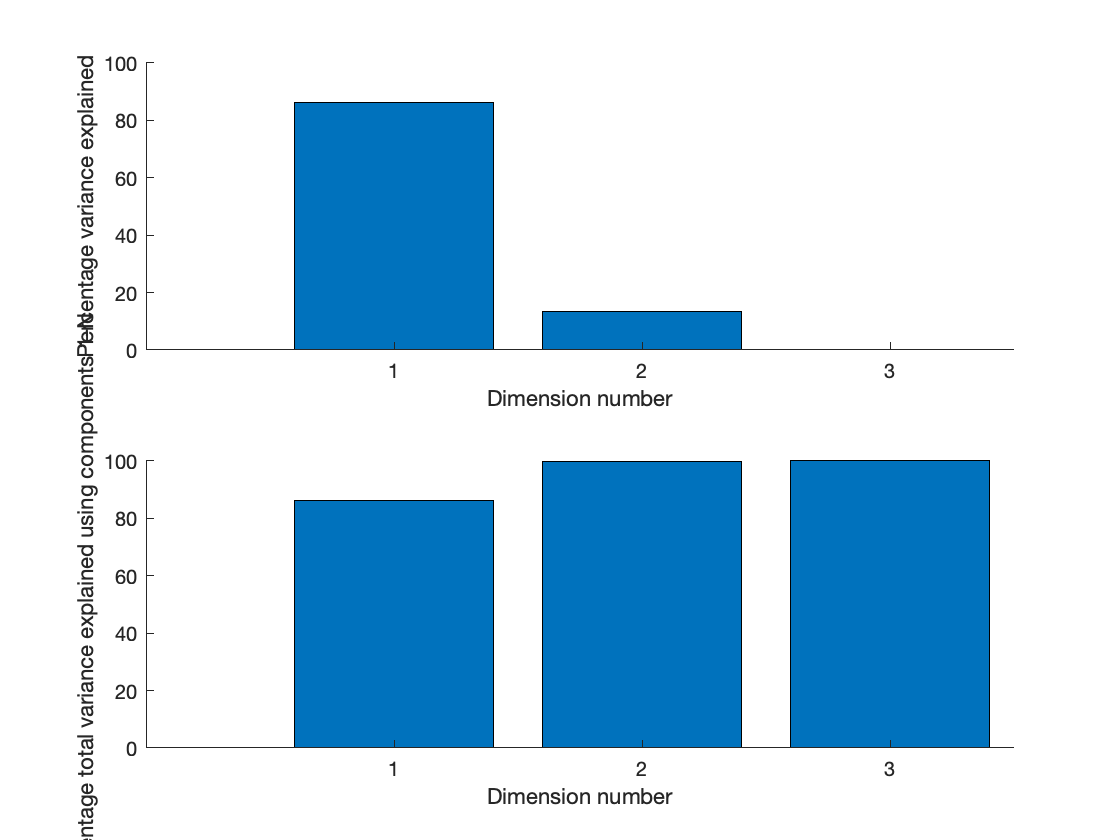


figure;
subplot(2,1,1);
bar(varexplained);
ylabel('Percentage variance explained');
xlabel('Dimension number');
box off;
axis([0 3.5 0 100]);

subplot(2,1,2);
bar(cumsum(varexplained));
ylabel('Percentage total variance explained using components 1-N');
xlabel('Dimension number');
box off;
axis([0 3.5 0 100]);

% How much variance explained by the first few dminesions in PC space?


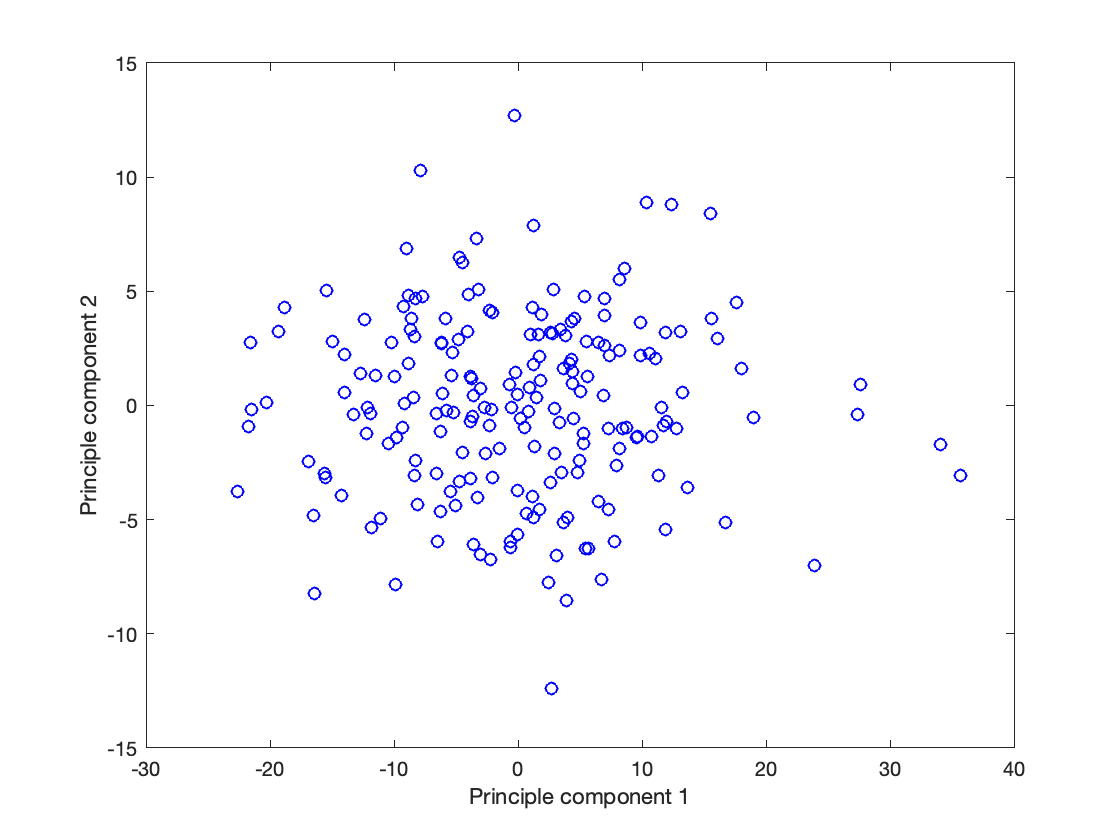



%-------------------------

% Project Data onto PC space
% 

% Projections are wrt mean, since Covariance matrix is used, so subtract
% means 
g_submean = g - repmat(mean(g,2),1,size(g,2)); % Subtract means
g_proj = comps' * g_submean;  % perform the projection

figure; 
% plot only the first 2 dimensions
plot(g_proj(1,:),g_proj(2,:),'bo');
xlabel('Principle component 1');
ylabel('Principle component 2');


% Q Does the 2-dimensional principle component projection resemble the 
% "best" view through the data in 3 dimensions


% -------------------------------------------